#  PID tuning via Bayesian Optimization

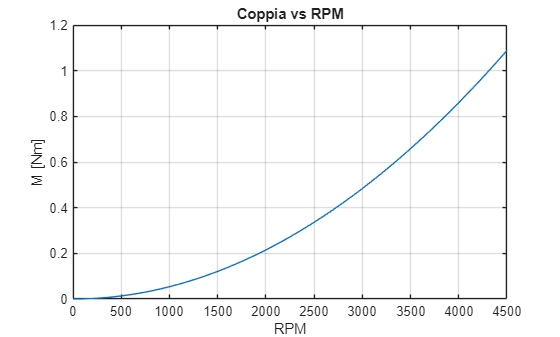

clear; clc;

%rng(1,'twister');


run("Baseline_last.mlx")

function J = jointPIDObjectiveWrapper(x, env)

    K.theta = [x.kp_theta, x.ki_theta, x.kd_theta];
    K.phi   = [x.kp_phi,   x.ki_phi,   x.kd_phi];
    K.psi   = [x.kp_psi,   x.ki_psi,   x.kd_psi];
    K.z     = [x.kp_z,     x.ki_z,     x.kd_z];

    % reset PID 
    clear evalPid_param

    % reset + sim
    [~, State] = resetFunction(env);
    [e, u, dt] = runFullClosedLoopSimulation(K, env, State);

    % ---- scaling ----
    escale = struct( ...
        'phi',   deg2rad(10), ...
        'theta', deg2rad(10), ...
        'psi',   deg2rad(10), ...
        'z',     5 ...
    );

    %    we = struct('phi',2.0,'theta',2.0,'psi',2.0,'z',25);     % error weights

    we = struct('phi',4.0,'theta',4.0,'psi',8.0,'z',16);     % error weights
    wu = struct('phi',1e-3,'theta',1e-3,'psi',1e-3,'z',1e-3); % effort weights
    wdu = struct('phi',5e-3,'theta',5e-3,'psi',5e-3,'z',50e-2);


    % alpha=1 => no smoothing, alpha small => stronger smoothing
    if isfield(env,'J_u_smooth_alpha')
        alpha = env.J_u_smooth_alpha;
    else
        alpha = 0.9;  
    end

    J = 0;
    fields = fieldnames(e);

    for i = 1:numel(fields)
        f = fields{i};

        % normalized error
        en = e.(f) / escale.(f);

        % effort signal
        un = u.(f);

        if alpha < 1.0
            us = zeros(size(un));
            us(1) = un(1);
            for k = 2:numel(un)
                us(k) = us(k-1) + alpha*(un(k) - us(k-1));
            end
        else
            us = un;
        end

        du = [0; diff(un)];  % u(k)-u(k-1)

        J = J + ( ...
            we.(f) * sum(en.^2) + ...
            wu.(f) * sum(us.^2) + ...
            wdu.(f) * sum((du/dt).^2) ...
        ) * dt;
    end

    % terminal penalty 
    J = J + 10*( (e.z(end)/escale.z)^2 + ...
                 (e.phi(end)/escale.phi)^2 + ...
                 (e.theta(end)/escale.theta)^2 + ...
                 (e.psi(end)/escale.psi)^2 );

    if ~isfinite(J)
        J = 1e6;
    end
end



## Variabili di ottimizzazione (4 PID × 3 parametri)

vars = [
    optimizableVariable('kp_theta',[-0 33])
    optimizableVariable('ki_theta',[0 1])
    optimizableVariable('kd_theta',[0 5])

    optimizableVariable('kp_phi',[-0 33])
    optimizableVariable('ki_phi',[0 1])
    optimizableVariable('kd_phi',[-0 5])

    optimizableVariable('kp_psi',[0 100])
    optimizableVariable('ki_psi',[0 1])
    optimizableVariable('kd_psi',[-0 20])

    optimizableVariable('kp_z',[-0 20])
    optimizableVariable('ki_z',[0 1])
    optimizableVariable('kd_z',[-0 8])
];

## Bayesian Optimization call

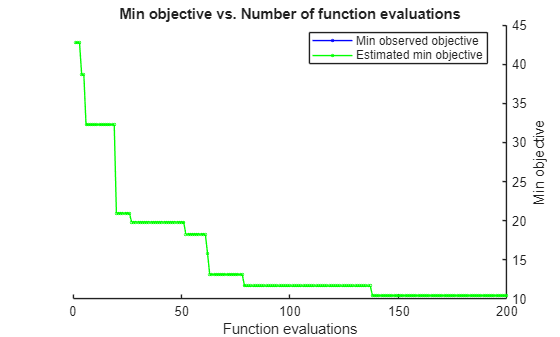

objFun = @(params) jointPIDObjectiveWrapper(params,env);

results = bayesopt(@(x) jointPIDObjectiveWrapper(x, env), vars, ...
    'MaxObjectiveEvaluations', 200, ...     
    'NumSeedPoints', 50, ...
    'IsObjectiveDeterministic', true, ...  
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'ExplorationRatio', 0.5, ...
    'Verbose', 0, ...
    'UseParallel', true, ...
    'PlotFcn', {@plotMinObjective,@plotObjectiveModel});

## Parametri ottimi


bestK = bestPoint(results);
disp('Guadagni PID ottimi:');

Guadagni PID ottimi:


disp(bestK);

    kp_theta    ki_theta    kd_theta    kp_phi    ki_phi     kd_phi     kp_psi    ki_psi     kd_psi     kp_z       ki_z       kd_z  
    ________    ________    ________    ______    _______    _______    ______    _______    ______    _______    _______    _______

     7.7149      0.2306      1.1804     3.8723    0.71273    0.31981    13.533    0.11315    2.7302    0.85843    0.88317    0.27806



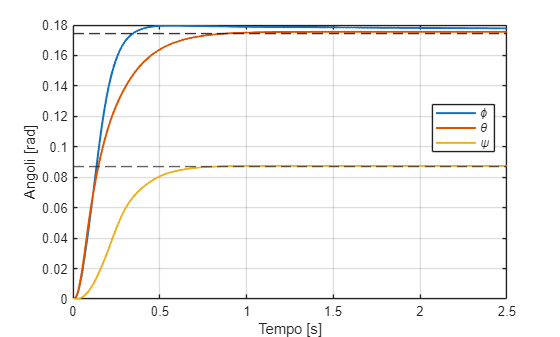


% Build K
K.theta = [bestK.kp_theta, bestK.ki_theta, bestK.kd_theta];
K.phi   = [bestK.kp_phi,   bestK.ki_phi,   bestK.kd_phi];
K.psi   = [bestK.kp_psi,   bestK.ki_psi,   bestK.kd_psi];
K.z     = [bestK.kp_z,     bestK.ki_z,     bestK.kd_z];

% Reset env/state
[~, State0] = resetFunction(env);

% Run final simulation 
[e, u, dt, log] = runFullClosedLoopSimulation(K, env, State0);

t = log.t;

% ====== PLOTS ======

% Angles 
figure('Name','Angles');
plot(t, log.ang(:,1), t, log.ang(:,2), t, log.ang(:,3), 'LineWidth', 1.5); grid on;
xlabel('Tempo [s]'); ylabel('Angoli [rad]');
legend('\phi','\theta','\psi','Location','best');
title('');

hold on;
yline(log.com_ang(1), '--', 'HandleVisibility','off');
yline(log.com_ang(2), '--', 'HandleVisibility','off');
yline(log.com_ang(3), '--', 'HandleVisibility','off');
hold off;

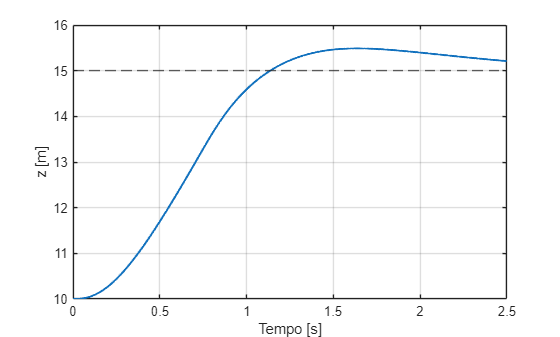



% Altitude tracking
figure('Name','Altitude');
plot(t, log.pos(:,3), 'LineWidth', 1.5); grid on;
xlabel('Tempo [s]'); ylabel('z [m]');
title('');
hold on; yline(log.com_alt, '--'); hold off;

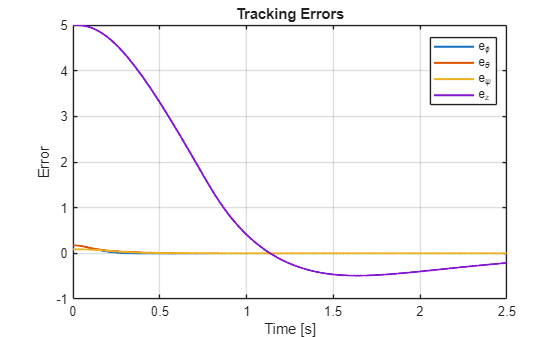


% Errors
figure('Name','Errors');
plot(t, e.phi, t, e.theta, t, e.psi, t, e.z, 'LineWidth', 1.5); grid on;
xlabel('Time [s]'); ylabel('Error');
legend('e_\phi','e_\theta','e_\psi','e_z','Location','best');
title('Tracking Errors');

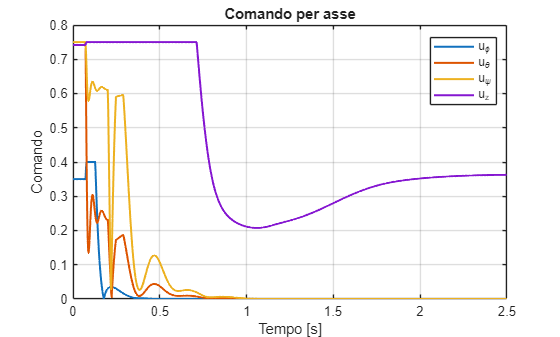


% Control "effort" 
figure('Name','Control Projections');
plot(t, u.phi, t, u.theta, t, u.psi, t, u.z, 'LineWidth', 1.5); grid on;
xlabel('Tempo [s]'); ylabel('Comando');
legend('u_\phi','u_\theta','u_\psi','u_z','Location','best');
title('Comando per asse');

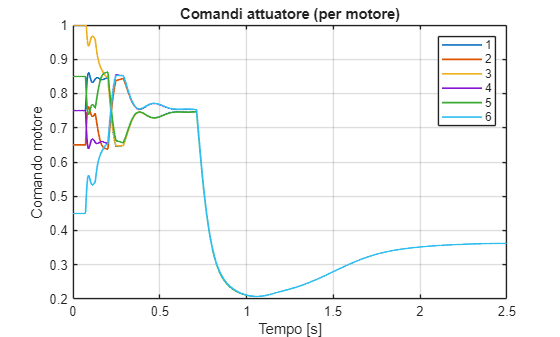


% raw actuator 
figure('Name','Comandi attuatore');
plot(t, log.action, 'LineWidth', 1.25); grid on;
xlabel('Tempo [s]'); ylabel('Comando motore');
title('Comandi attuatore (per motore)');
legend("1","2","3","4","5","6")

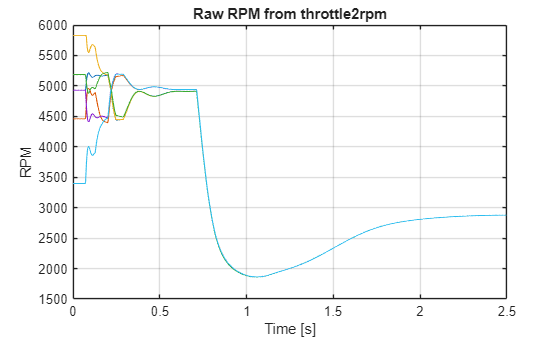

figure('Name','RPM raw vs smoothed');
plot(log.t, log.rpm_raw, 'LineWidth', 0.8); grid on;
xlabel('Time [s]'); ylabel('RPM'); title('Raw RPM from throttle2rpm');

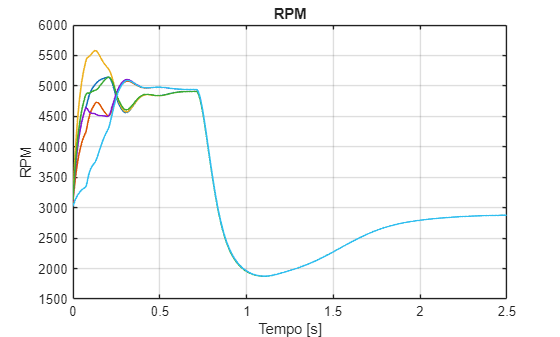


figure('Name','Smoothed RPM (used in dynamics)');
plot(log.t, log.rpm_smooth, 'LineWidth', 1.2); grid on;
xlabel('Tempo [s]'); ylabel('RPM'); title('RPM');

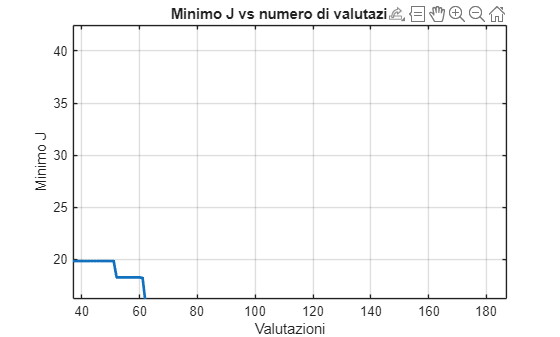

plot(results.EstimatedObjectiveMinimumTrace, LineWidth=2);
grid on
title("Minimo J vs numero di valutazioni")
xlabel("Valutazioni")
ylabel("Minimo J")